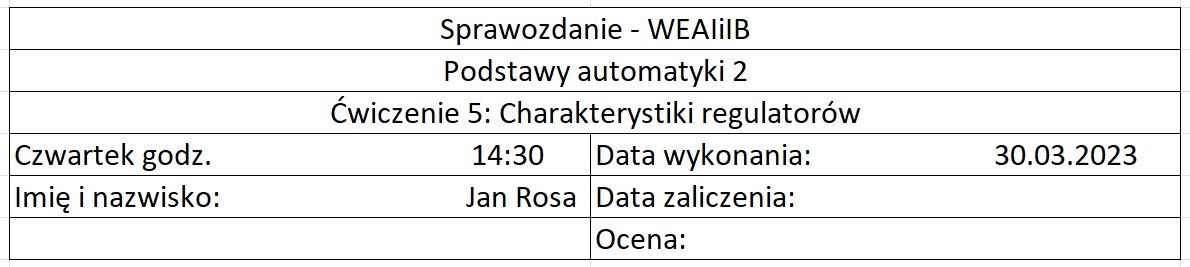 

## Cel ćwiczenia 

Celem ćwiczenia jest zapoznanie się z charakterystykami czasowymi i częstotliwościowymi podstawowych typów regulatorów ciągłych, omawianych na wykładzie i podczas ćwiczeń audytoryjnych. Podczas ćwiczenia należy zbadać następujące regulatory:

## PI

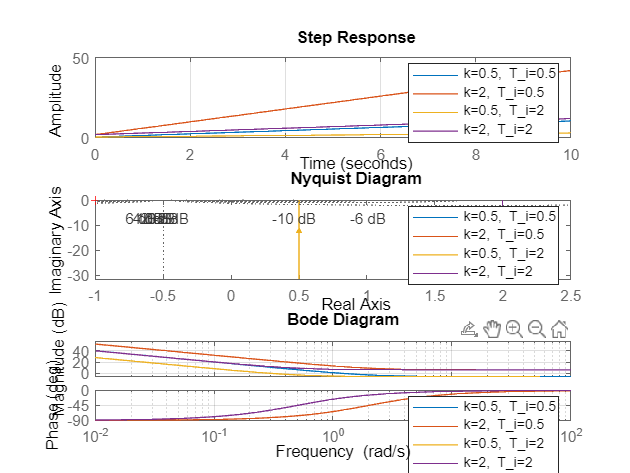

k_vec = [0.5 2];
ti_vec = [0.5 2];
t_vec = linspace(0, 10, 100);
obiekty = {};
legendt = {};
legenddt = [];
for i = 1:2
    for j = 1:2
        obiekt = k_vec(j) * (1 + tf([0 1], [ti_vec(i) 0]));
        obiekty{2*i + j -2} = obiekt;
        legendt{2*i + j -2} = "k=" +string(k_vec(j)) + ", T_i=" + string(ti_vec(i));
    end
end
wykres(obiekty, t_vec, legendt)

## PD

k_vec = [0.5 2];
td_vec = [6 21];
tdd_vec = [0.5 2];
t_vec = linspace(0, 10, 100);
obiekty = {};
legendt = {};


legendt =

  0×0 empty cell array



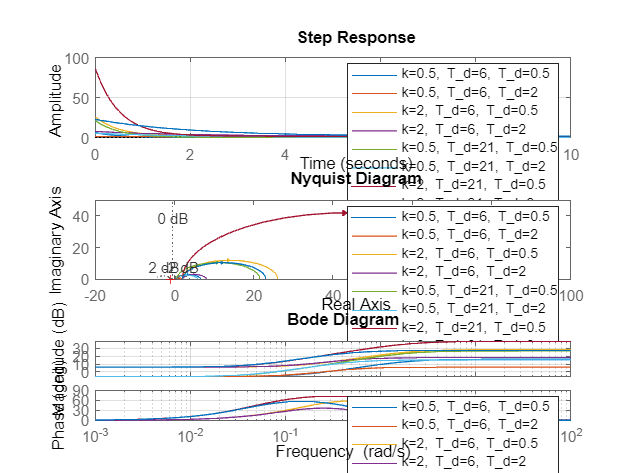

for i = 1:2
    for j = 1:2
        for k = 1:2
            obiekt = k_vec(j) * (1 + tf([td_vec(i) 0], [tdd_vec(k) 1]));
            obiekty{4*i + 2*j + k - 6} = obiekt;
            legendt{4*i + 2*j + k - 6} = "k=" +string(k_vec(j)) + ", T_d=" + string(td_vec(i)) + ", T_d=" + string(tdd_vec(k));
        end
    end
end
wykres(obiekty, t_vec, legendt)

## PID

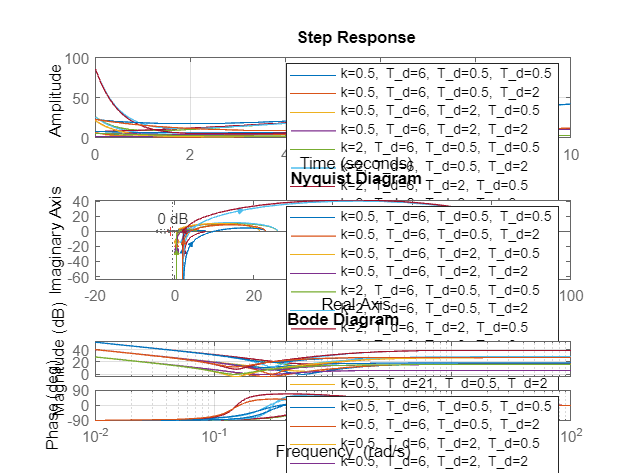

k_vec = [0.5 2];
td_vec = [6 21];
tdd_vec = [0.5 2];
ti_vec = [0.5 2];
t_vec = linspace(0, 10, 100);
obiekty = {};
legendt = {};
for i = 1:2
    for j = 1:2
        for k = 1:2
            for l = 1:2
                obiekt = k_vec(j) * (1 + tf([td_vec(i) 0], [tdd_vec(k) 1]) + tf([0 1], [ti_vec(l) 0]));
                obiekty{8*i + 4*j + 2*k + l - 14} = obiekt;
                legendt{8*i + 4*j + 2*k + l - 14} = "k=" +string(k_vec(j)) + ", T_d=" + string(td_vec(i)) + ", T_d=" + string(tdd_vec(k)) + ", T_d=" + string(ti_vec(l));
            end
        end
    end
end
wykres(obiekty, t_vec, legendt)

function [] = wykres(obiekty, t, legendt)
    lnt = size(obiekty);
    lnt = lnt(2);
    f = figure();
    f.Position = [488 342 800 830];
    subplot(3, 1, 1)
    for i = 1:lnt
        step(obiekty{i}, t);
        grid on;
        hold on;
    end
    legend(legendt)
    subplot(3, 1, 2)
    plotooptions = nyquistoptions("cstprefs");
    plotooptions.ShowFullContour = 'off';
    for i = 1:lnt
        nyquist(obiekty{i}, plotooptions);
        grid on;
        hold on;
    end
    legend(legendt)
    subplot(3, 1, 3)
    for i = 1:lnt
        bode(obiekty{i});
        grid on;
        hold on;
    end
    legend(legendt)
end

### Wnioski

Ćwiczenie pozwoliło zapoznać się z charakterystykami regulatorów.